
columns = {'redshift','tu','tg','tr','ti','tz','ty', 'u10','uerr10','g10','gerr10','r10','rerr10','i10','ierr10','z10','zerr10','y10','yerr10'};

% training data
load /Users/troyraen/Korriban/Documents/MLProject/data/CGsample.dat
cgs = CGsample(:,3:end); % strip df index and galaxy id
dat = cgs(:,2:end); % everything but redshift
specz = cgs(:,1); % true redshift

% testing data
load /Users/troyraen/Korriban/Documents/MLProject/data/CGsample4.dat
test_cgs = CGsample4(1:10000,3:end); % strip df index and galaxy id. first 10000 rows
test_dat = test_cgs(:,2:end); % everything but redshift
test_specz = test_cgs(:,1); % true redshift

## Random Forest

mdl = fitrensemble(dat,specz);
res = predict(mdl, dat);

% [NMAD, out10] = calc_zerrors(test_specz, test_res)
[NMAD, out10] = calc_zerrors(specz, res)

NMAD = 0.0368

out10 = 0.1191

mse = resubLoss(mdl)

mse = 0.0251

nsamp=[1000, 2500, 5000, 10000, 15000, 20000];
nsamp=[10000];
ln = length(nsamp);
errs = zeros(3,ln); % row 1 = NMAD, 2 = out10, 3 = mse

n = 1;
for i=1:ln
    nm1 = n;
    n = nsamp(i)
    if n>10000
        nm1=1;
    end
    datn = dat(nm1:nm1+n-1,:);
    length(datn)
    zn = specz(nm1:nm1+n-1);
    
    [mdl, res, mse, test_res] = do_fitrensemble(datn, zn, test_dat);
    
    [NMAD, out10] = calc_zerrors(test_specz, test_res)
    errs(1,i) = NMAD;
    errs(2,i) = out10;
    errs(3,i) = mes;
end

n = 10000

ans = 10000

|===================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Method | NumLearningC-|    LearnRate |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              | ycles        |              |              |
|===================================================================================================================================|
|    1 | Best   |    0.051564 |       21.59 |    0.051564 |    0.051564 |          Bag |           31 |            - |           17 |
|    2 | Accept |     0.36851 |      43.386 |    0.051564 |    0.073484 |          Bag |          224 |            - |         1168 |
|    3 | Accept |     0.24645 |      16.328 |    0.051564 |    0.051584 |          Bag |           72 |            - |          598 |
|    4 | Best   |    0.031981 |      378.07 |    0.031981 |   

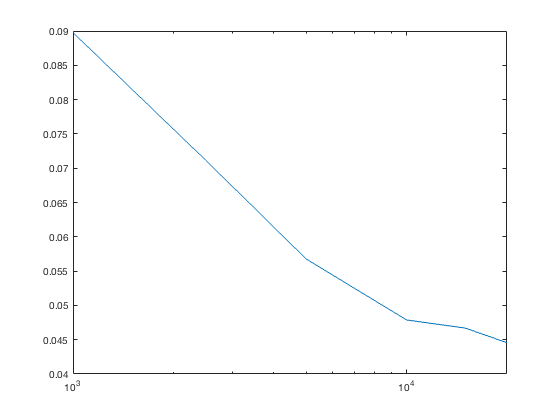

semilogx(nsamp,errs(1,:))

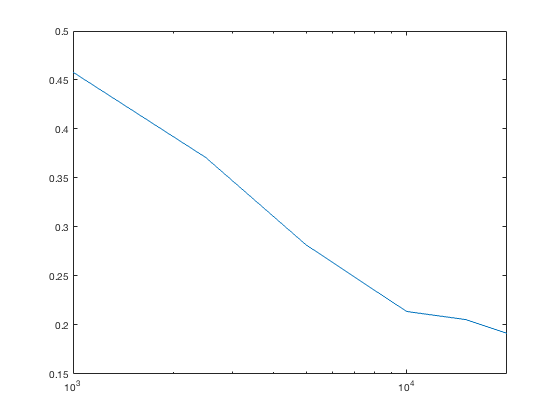

semilogx(nsamp,errs(2,:))

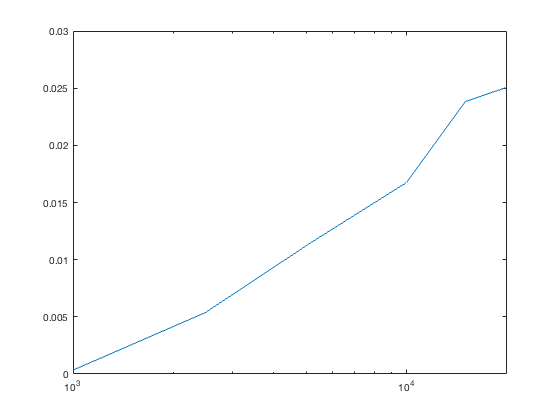

semilogx(nsamp,errs(3,:))

## Neural Net

ulayers = [1] % train with 1 hidden layer, 1 hidden units

ulayers = 1

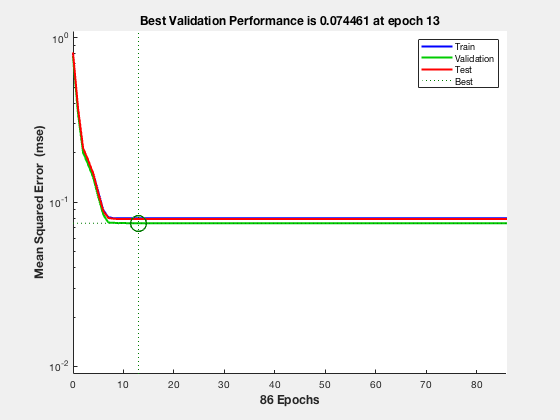

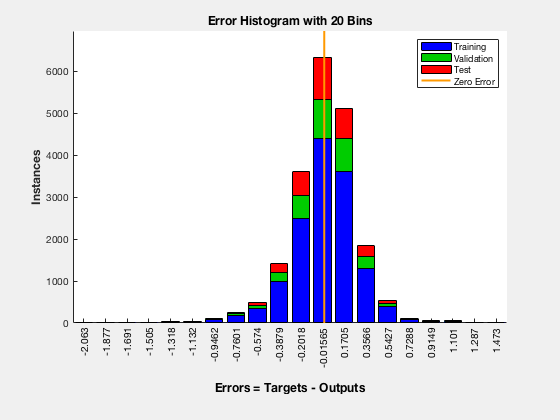

[net, res, mse1] = do_fitnet(ulayers, dat, specz);

mse1

mse1 = 0.0788


ulayers = [5] % train with 1 hidden layer, 5 hidden units

ulayers = 5

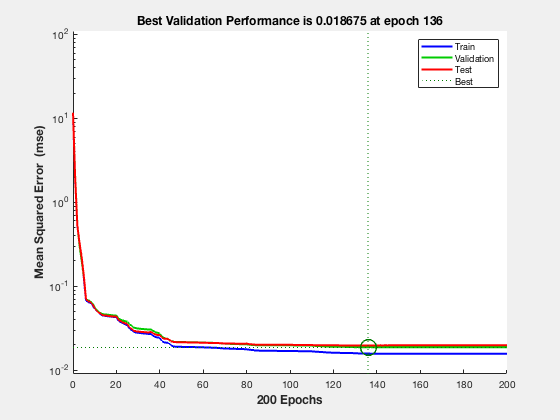

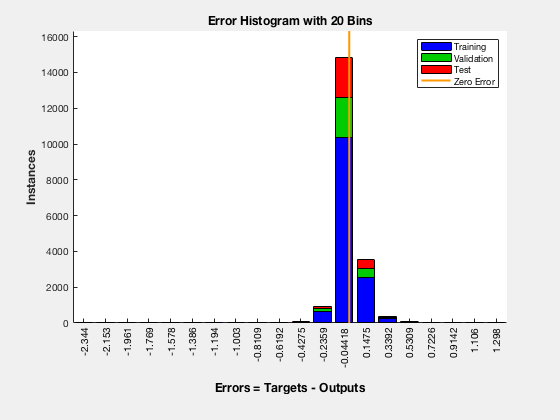

[net, res, mse5] = do_fitnet(ulayers, dat, specz);

mse5

mse = 0.0168

ulayers = [10,10] % train with 2 hidden layers, 10 hidden units each

ulayers =     10    10


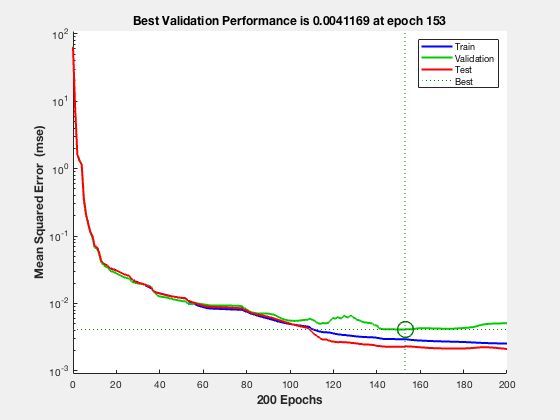

[net, res, mse10] = do_fitnet(ulayers, dat, specz);

mse10

mse10 = 0.0030

ulayers = [15,15,15]

ulayers =     15    20    10


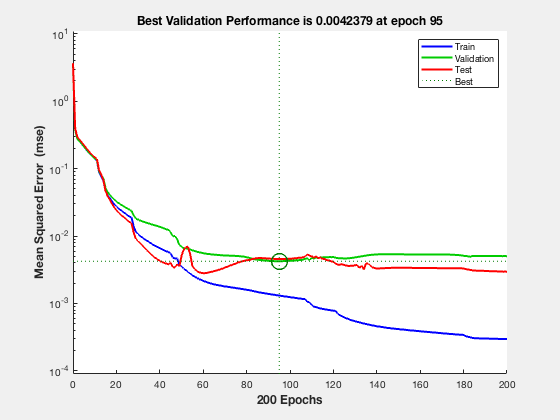

[net, res, mse15] = do_fitnet(ulayers, dat, specz);

mse15

mse3 = 0.0022

ulayers = [10,10] % train with 2 hidden layers, 10 hidden units each

ulayers =     10    10



nsamp=[1000, 2500, 5000, 10000];%, 15000, 20000];
ln = length(nsamp);
errs = zeros(3,ln); % row 1 = NMAD, 2 = out10, 3 = mse

n = 1;
for i=1:ln
    nm1 = n;
    n = nsamp(i)
    if n>10000
        nm1=1;
    end
    datn = dat(nm1:nm1+n-1,:);
    length(datn)
    zn = specz(nm1:nm1+n-1);
    
    [net, res, mse10, test_res] = do_fitnet(ulayers, datn, zn, test_dat);
    
    [NMAD, out10] = calc_zerrors(test_specz, test_res)
    errs(1,i) = NMAD;
    errs(2,i) = out10;
    errs(3,i) = mse10;
end

n = 1000

ans = 1000

NMAD = 0.0079

out10 = 0.0213

n = 2500

ans = 2500

NMAD = 0.0158

out10 = 0.0345

n = 5000

ans = 5000

NMAD = 0.0119

out10 = 0.0162

n = 10000

ans = 10000

NMAD = 0.0090

out10 = 0.0099

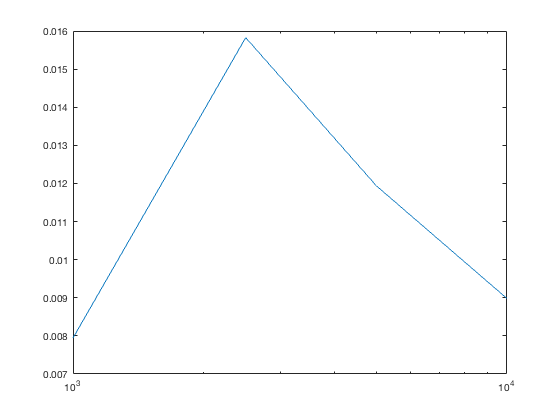

semilogx(nsamp,errs(1,:))

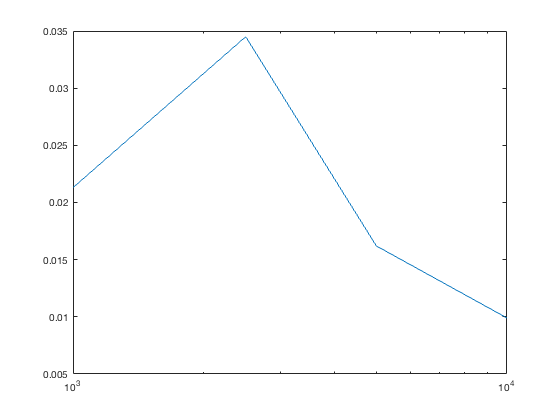

semilogx(nsamp,errs(2,:))